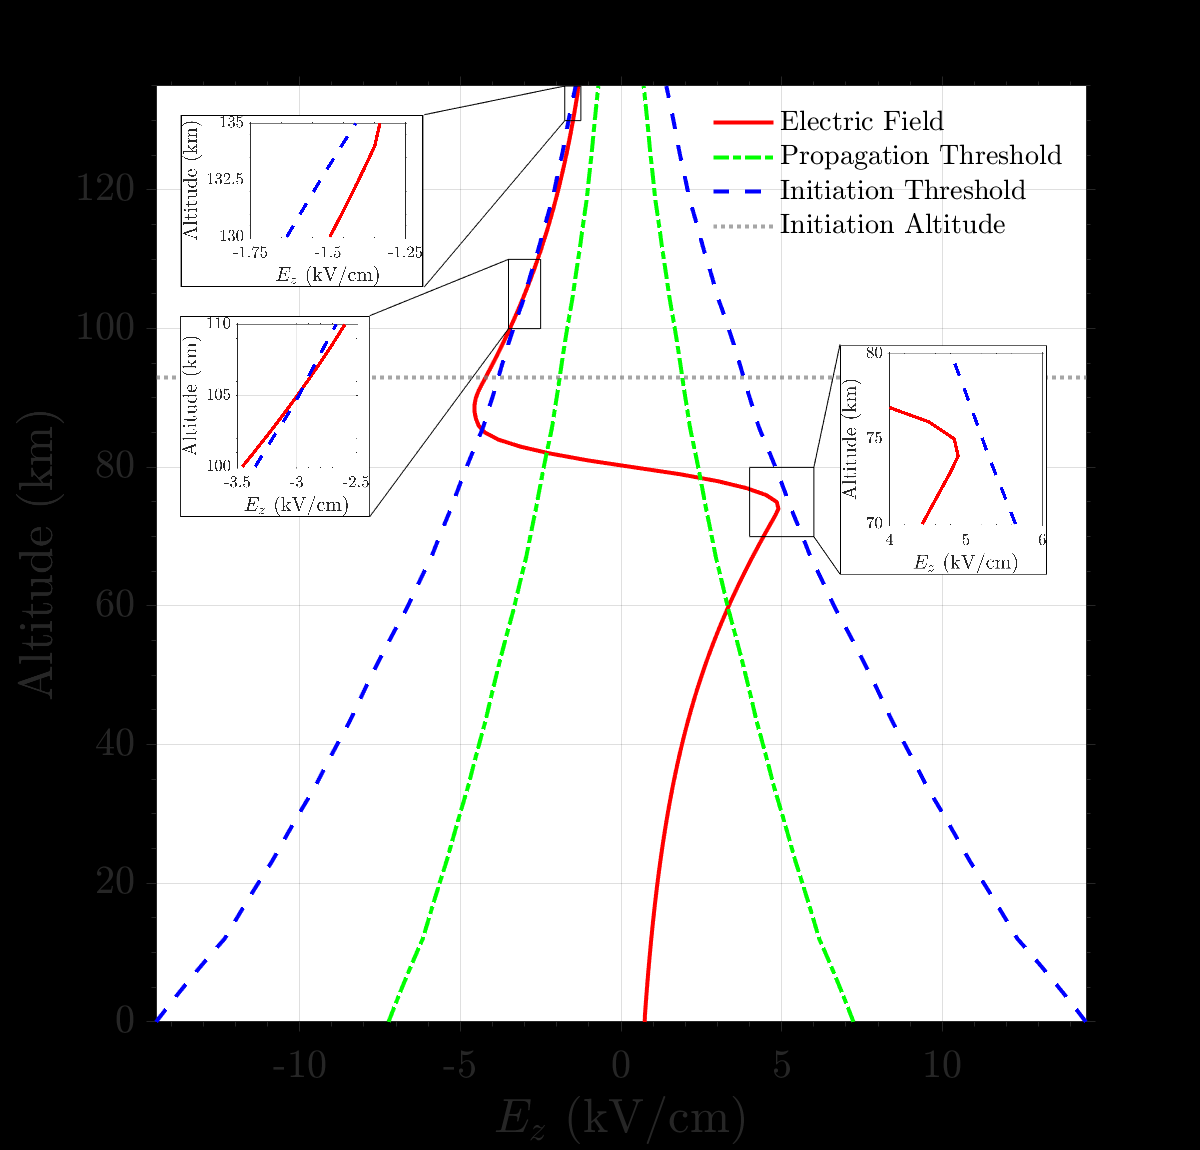

clf
clearvars -except sims
close all

% If the zoomed-in images are already saved, set to 1, else 0:
ready2embed = 1;
highRes     = 0;
titleFont   = 32;
labelFont   = 24;
legendFont  = 14;
numberFont  = 20;

% Streamers: 600 x 1200; Leaders: 600 x 575
positionWidth  = 600;
positionHeight = 575;
legendLocation = 'northeast';
initiationHeight = 93;

% Zoomed in regions to include:
zoom.TopLeft     = 1;
zoom.TopRight    = 0;
zoom.BottomLeft  = 1;
zoom.BottomRight = 1;

% Ratio to stretch width of embedded image by:
stretch.TopLeft     = 3;
stretch.TopRight    = 1;
stretch.BottomLeft  = 2;
stretch.BottomRight = 1;

% Definitions for top-left inlay (zoom.TopLeft == 1):
xi_TL = -1.75;      % Minimum electric field (kV/cm) to zoom into
xf_TL = -1.25;      % Maximum electric field (kV/cm) to zoom into
yi_TL = 130;        % Minimum domain height (km) to zoom into
yf_TL = 135;        % Maximum domain height (km) to zoom into
axis_x_TL = 0.15;   % Normalized location for x-position of top left inlay
axis_y_TL = 0.75;   % Normalized location for y-position of top left inlay
axis_h_TL = 0.15;   % Normalized height of top left inlay

% Definitions for top-right inlay (zoom.TopRight == 1):
xi_TR = -0.12;        % Minimum electric field (kV/cm) to zoom into
xf_TR = 0.12;        % Maximum electric field (kV/cm) to zoom into
yi_TR = 315;         % Minimum domain height (km) to zoom into
yf_TR = 325;         % Maximum domain height (km) to zoom into
axis_x_TR = 0.583;    % Normalized location for x-position of top right inlay 
axis_y_TR = 0.7;    % Normalized location for y-position of top right inlay 
axis_h_TR = 0.2;    % Normalized height of top right inlay

% Definitions for bottom-left inlay (zoom.BottomLeft == 1):
xi_BL = -3.5;       % Minimum electric field (kV/cm) to zoom into
xf_BL = -2.5;       % Maximum electric field (kV/cm) to zoom into
yi_BL = 100;        % Minimum domain height (km) to zoom into
yf_BL = 110;        % Maximum domain height (km) to zoom into
axis_x_BL = 0.15;   % Normalized location for x-position of bottom left inlay
axis_y_BL = 0.55;   % Normalized location for y-position of bottom left inlay
axis_h_BL = 0.175;  % Normalized height of bottom left inlay

% Definitions for bottom-right inlay (zoom.BottomRight == 1):
xi_BR = 4.0;        % Minimum electric field (kV/cm) to zoom into
xf_BR = 6.0;        % Maximum electric field (kV/cm) to zoom into
yi_BR = 70;         % Minimum domain height (km) to zoom into
yf_BR = 80;         % Maximum domain height (km) to zoom into
axis_x_BR = 0.7;    % Normalized location for x-position of bottom right inlay
axis_y_BR = 0.5;    % Normalized location for y-position of bottom right inlay
axis_h_BR = 0.2;    % Normalized height of bottom right inlay

if ~exist('sims','var') || ~isfield(sims,'pathPNGs') || ~isfield(sims,'pathVideos')
    prompt1 = "\nWhat is the planetary body that the simulation is focused on? (No quotation marks needed for string input)\n-->";
    sims.objectName = input(prompt1,'s');
    prompt2 = "\nWhat type of discharge is this? (Leader / Streamer)\n-->";
    sims.objectType = input(prompt2,'s');
    while ~strcmp(sims.objectType,'Streamer') && ~strcmp(sims.objectType,'Leader')
        fprintf('\n\tNot an acceptable input. Please enter Streamer or Leader.\n');
        sims.objectType = input(prompt2,'s');
    end

    % Settings to ensure proper directory referencing:
    sims.pathPNGs = ['../Figures/',sims.objectName,'/',sims.objectType,'/PNGs'];
    if ~exist(sims.pathPNGs,'dir')
        mkdir(sims.pathPNGs);
    end
    sims.pathVideos = ['../Figures/',sims.objectName,'/',sims.objectType,'/Videos'];
    if ~exist(sims.pathVideos,'dir')
        mkdir(sims.pathVideos);
    end
end 

%% Compile and Run C++ code
cd ../results

%% Plot results

dxyz        = load('dxyz.dat');
Nxyz        = load('Nxyz.dat');
EzNumBF     = load('EnumBF.dat');
phiNumBF    = load('phiNumBF.dat');
Einitiation = load('Einitiation.dat');
EthPositive = load('EthPositive.dat');
EthNegative = load('EthNegative.dat');
z_gnd       = load('z_gnd.dat');

dz = dxyz(3);
Nz = Nxyz(3);
Lz = (Nz-1)*dz;
z  = (0:Nz-1)*dz+z_gnd;
clear dxyz Nxyz
if length(EthNegative)~=length(EzNumBF)
    fprintf('\nMismatching data set sizes, ensure simulation parameters are correctly executed.\n');
    cd ../viz
    return;
end

% Initializing threshold plot:
if ready2embed == 0
    linewidth = 4;
elseif ready2embed == 1
    linewidth = 2;
else
    fprintf('\nInvalid input for ~ready2embed~ variable, should be 0 or 1.\n');
    
end
figure;
set(gcf,'Position',[0,0,positionWidth,positionHeight]);
hold on
% Shows the charge layer's induced electric field before initiation:
plot(EzNumBF(:)*1e-5, z*1e-3, 'r-','LineWidth',linewidth,'DisplayName','Electric Field')
% Shows the propagation threshold:
plot(EthNegative(:)*1e-5,z*1e-3, 'g-.','LineWidth',linewidth,'HandleVisibility','off')
plot(EthPositive(:)*1e-5,z*1e-3, 'g-.','LineWidth',linewidth,'DisplayName','Propagation Threshold')
% Shows the initiation threshold:
plot(-1*Einitiation(:)*1e-5,z*1e-3, 'b--','LineWidth',linewidth,'HandleVisibility','off')
plot(Einitiation(:)*1e-5,z*1e-3, 'b--','LineWidth',linewidth,'DisplayName','Initiation Threshold')
yline(initiationHeight,':','Color',[0.5 0.5 0.5],'LineWidth',linewidth,'DisplayName','Initiation Altitude')

% Ensures proper formatting of image: 
set(gcf,'Position',[0,0,positionWidth,positionHeight]); 
axis([-1*max(Einitiation)*1e-5 1*max(Einitiation)*1e-5 0 ((Lz+z_gnd)*1e-3)]);
plotInfo = get(gca,'Position');

% Defining zoomed-in region 1 (bottom right-side of plot):
if zoom.BottomRight == 1
    if ready2embed == 0
        ratio_BR = stretch.BottomRight*(((xf_BR-xi_BR)*((Lz+z_gnd)*1e-3))/((yf_BR-yi_BR)*(2*max(Einitiation*1e-5))));
    elseif ready2embed == 1
        ratio_BR = (positionHeight/positionWidth)*size(imread([sims.pathPNGs,'/Ezoom_BottomRight.png']),2)/size(imread([sims.pathPNGs,'/Ezoom_BottomRight.png']),1);
        topx_BR = [xf_BR,(max(Einitiation*1e-5)*((((2*axis_x_BR)-(2*plotInfo(1))-plotInfo(3))/plotInfo(3))))];
        topy_BR = [yf_BR,(((axis_y_BR+axis_h_BR-plotInfo(2))/plotInfo(4))*(Lz+z_gnd)*1e-3)];
        bottomx_BR = topx_BR;
        bottomy_BR = [yi_BR,(((axis_y_BR-plotInfo(2))/plotInfo(4))*(Lz+z_gnd)*1e-3)];
        rectangle('Position',[xi_BR yi_BR (xf_BR - xi_BR) (yf_BR - yi_BR)],'EdgeColor','k','LineStyle','-');
        line(topx_BR,topy_BR,'HandleVisibility','off','Color','k');
        line(bottomx_BR,bottomy_BR,'HandleVisibility','off','Color','k');
    end
end

% Defining zoomed-in region 2 (bottom left-side of plot):
if zoom.BottomLeft == 1
    if ready2embed == 0
        ratio_BL = stretch.BottomLeft*(((xf_BL-xi_BL)*((Lz+z_gnd)*1e-3))/((yf_BL-yi_BL)*(2*max(Einitiation*1e-5))));
    elseif ready2embed == 1
        ratio_BL = (positionHeight/positionWidth)*(size(imread([sims.pathPNGs,'/Ezoom_BottomLeft.png']),2)/size(imread([sims.pathPNGs,'/Ezoom_BottomLeft.png']),1));
        topx_BL = [xi_BL,(-1*max(Einitiation*1e-5)*(1-((2*(axis_x_BL+(ratio_BL*axis_h_BL)-plotInfo(1)))/plotInfo(3))))];
        topy_BL = [yf_BL,(((axis_y_BL+axis_h_BL-plotInfo(2))/plotInfo(4))*(Lz+z_gnd)*1e-3)];
        bottomx_BL = topx_BL;
        bottomy_BL = [yi_BL,(((axis_y_BL-plotInfo(2))/plotInfo(4))*(Lz+z_gnd)*1e-3)];
        rectangle('Position',[xi_BL yi_BL (xf_BL - xi_BL) (yf_BL - yi_BL)],'EdgeColor','k','LineStyle','-')
        line(topx_BL,topy_BL,'HandleVisibility','off','Color','k');
        line(bottomx_BL,bottomy_BL,'HandleVisibility','off','Color','k');
    end
end

% Defining zoomed-in region 3 (top left-side of plot):
if zoom.TopLeft == 1
    if ready2embed == 0
        ratio_TL = stretch.TopLeft*(((xf_TL-xi_TL)*((Lz+z_gnd)*1e-3))/((yf_TL-yi_TL)*(2*max(Einitiation*1e-5))));
    elseif ready2embed == 1
        ratio_TL = (positionHeight/positionWidth)*size(imread([sims.pathPNGs,'/Ezoom_TopLeft.png']),2)/size(imread([sims.pathPNGs,'/Ezoom_TopLeft.png']),1);
        topx_TL = [xi_TL,(-1*max(Einitiation*1e-5)*(1-((2*(axis_x_TL+(ratio_TL*axis_h_TL)-plotInfo(1)))/plotInfo(3))))];
        topy_TL = [yf_TL,(((axis_y_TL+axis_h_TL-plotInfo(2))/plotInfo(4))*(Lz+z_gnd)*1e-3)];
        bottomx_TL = topx_TL;
        bottomy_TL = [yi_TL,(((axis_y_TL-plotInfo(2))/plotInfo(4))*(Lz+z_gnd)*1e-3)];
        rectangle('Position',[xi_TL yi_TL (xf_TL - xi_TL) (yf_TL - yi_TL)],'EdgeColor','k','LineStyle','-')
        line(topx_TL,topy_TL,'HandleVisibility','off','Color','k');
        line(bottomx_TL,bottomy_TL,'HandleVisibility','off','Color','k');
    end
end

% Defining zoomed-in region 4 (top right-side of plot):
if zoom.TopRight == 1
    if ready2embed == 0
        ratio_TR = stretch.TopRight*(((xf_TR-xi_TR)*((Lz+z_gnd)*1e-3))/((yf_TR-yi_TR)*(2*max(Einitiation*1e-5))));
    elseif ready2embed == 1
        ratio_TR = (positionHeight/positionWidth)*size(imread([sims.pathPNGs,'/Ezoom_TopRight.png']),2)/size(imread([sims.pathPNGs,'/Ezoom_TopRight.png']),1);
        topx_TR = [xf_TR,(max(Einitiation*1e-5)*((((2*axis_x_TR)-(2*plotInfo(1))-plotInfo(3))/plotInfo(3))))];
        topy_TR = [yf_TR,(((axis_y_TR+axis_h_TR-plotInfo(2))/plotInfo(4))*(Lz+z_gnd)*1e-3)];
        bottomx_TR = topx_TR;
        bottomy_TR = [yi_TR,(((axis_y_TR-plotInfo(2))/plotInfo(4))*(Lz+z_gnd)*1e-3)];
        rectangle('Position',[xi_TR yi_TR (xf_TR - xi_TR) (yf_TR - yi_TR)],'EdgeColor','k','LineStyle','-');
        line(topx_TR,topy_TR,'HandleVisibility','off','Color','k');
        line(bottomx_TR,bottomy_TR,'HandleVisibility','off','Color','k');
    end
end

% Ensuring formatting of macro-image:
hold off
legend('Interpreter','latex','FontSize',legendFont,'location',legendLocation,'Box','off')
set(gca,'FontSize',numberFont,'Layer','bottom');
set(gca,'XMinorTick','on','YMinorTick','on','Tickdir','out','TickLabelInterpreter','latex')
box on
grid on
title('(a)','Interpreter','latex','FontSize',titleFont,'Units','normalized');
titleInfo = get(gca,'title');
set(titleInfo,'Position', [((titleInfo.Extent(3)/2)-((titleInfo.Parent.InnerPosition(1)/titleInfo.Parent.InnerPosition(3)))) 1.004 0]);
%title(['Electric Field Thresholds: ',sims.objectName, ' (',sims.objectType,')'],'Interpreter','latex','FontSize',28);
xlabel('$E_z$ (kV/cm)','FontSize',labelFont,'Interpreter','latex');
ylabel('Altitude (km)','FontSize',labelFont,'Interpreter','latex');

%set(gcf,'color','none')
%return
if ready2embed == 1
    % Embedding zoomed-in images:
    if zoom.BottomRight == 1
        ax_BR = axes('pos',[axis_x_BR axis_y_BR ratio_BR*axis_h_BR axis_h_BR]);
        set(gca,'color','none')
        set(gcf,'color','none')
        imshow(padarray(imread([sims.pathPNGs,'/Ezoom_BottomRight.png']),[10 10],0,'both'));
    end

    if zoom.BottomLeft == 1
        ax_BL = axes('pos',[axis_x_BL axis_y_BL ratio_BL*axis_h_BL axis_h_BL]);
        set(gca,'color','none')
        set(gcf,'color','none')
        imshow(padarray(imread([sims.pathPNGs,'/Ezoom_BottomLeft.png']),[10 10],0,'both'));
        set(gcf,'color','none')
    end

    if zoom.TopLeft == 1
        ax_TL = axes('pos',[axis_x_TL axis_y_TL ratio_TL*axis_h_TL axis_h_TL]);
        set(gca,'color','none')
        set(gcf,'color','none')
        imshow(padarray(imread([sims.pathPNGs,'/Ezoom_TopLeft.png']),[10 10],0,'both'));
        set(gcf,'color','none')
    end

    if zoom.TopRight == 1
        ax_TR = axes('pos',[axis_x_TR axis_y_TR ratio_TR*axis_h_TR axis_h_TR]);
        set(gca,'color','none')
        set(gcf,'color','none')
        imshow(padarray(imread([sims.pathPNGs,'/Ezoom_TopRight.png']),[10 10],0,'both'));
        set(gcf,'color','none')
    end

    % Exporting to .pdf with transparent framing:
    set(gcf,'Position',[0,0,positionWidth,positionHeight])
    set(gcf,'Resize','off')
    if highRes == 1
        currentFolder = pwd;
        cd(sims.pathPNGs);
        export_fig /InlayThreshold.png -transparent -m8
        cd(currentFolder);
    else
        exportgraphics(gcf,[sims.pathPNGs,'/InlayThreshold_',sims.objectName,'_',sims.objectType,'.png'],'BackgroundColor','white','Resolution',600);
    end
    cd ../viz
else
    % Formatting for zoomed-in regions:
    legend off
    title '' 
    
    % Zoomed-in region 1:
    if zoom.BottomRight == 1
        xlim([xi_BR xf_BR]);
        ylim([yi_BR yf_BR]);
        set(gcf,'Position',[0,0,ratio_BR*round(2.5*positionHeight*axis_h_BR),round(2.5*positionHeight*axis_h_BR)]);
        xticks([xi_BR (xi_BR+xf_BR)/2 xf_BR]);
        xticklabels({num2str(xi_BR),num2str((xi_BR+xf_BR)/2),num2str(xf_BR)});
        yticks([yi_BR (yi_BR+yf_BR)/2 yf_BR]);
        yticklabels({num2str(yi_BR),num2str((yi_BR+yf_BR)/2),num2str(yf_BR)});
        set(gcf,'Position',[0,0,ratio_BR*round(2.5*positionHeight*axis_h_BR),round(2.5*positionHeight*axis_h_BR)]);
        exportgraphics(gcf,[sims.pathPNGs,'/Ezoom_BottomRight.png'],'Resolution',600);
    end
    
    % Zoomed-in region 2:
    if zoom.BottomLeft == 1
        xlim([xi_BL xf_BL]);
        ylim([yi_BL yf_BL]);
        set(gcf,'Position',[0,0,ratio_BL*round(2.5*positionHeight*axis_h_BL),round(2.5*positionHeight*axis_h_BL)]);
        xticks([xi_BL (xi_BL+xf_BL)/2 xf_BL]);
        xticklabels({num2str(xi_BL),num2str((xi_BL+xf_BL)/2),num2str(xf_BL)});
        yticks([yi_BL (yi_BL+yf_BL)/2 yf_BL]);
        yticklabels({num2str(yi_BL),num2str((yi_BL+yf_BL)/2),num2str(yf_BL)});
        set(gcf,'Position',[0,0,ratio_BL*round(2.5*positionHeight*axis_h_BL),round(2.5*positionHeight*axis_h_BL)]);
        exportgraphics(gcf,[sims.pathPNGs,'/Ezoom_BottomLeft.png'],'Resolution',600);
    end

    % Zoomed-in region 3:
    if zoom.TopLeft == 1
        xlim([xi_TL xf_TL]);
        ylim([yi_TL yf_TL]);
        set(gcf,'Position',[0,0,ratio_TL*round(2.5*positionHeight*axis_h_TL),round(2.5*positionHeight*axis_h_TL)]);
        xticks([xi_TL (xi_TL+xf_TL)/2 xf_TL]);
        xticklabels({num2str(xi_TL),num2str((xi_TL+xf_TL)/2),num2str(xf_TL)});
        yticks([yi_TL (yi_TL+yf_TL)/2 yf_TL]);
        yticklabels({num2str(yi_TL),num2str((yi_TL+yf_TL)/2),num2str(yf_TL)});
        set(gcf,'Position',[0,0,ratio_TL*round(2.5*positionHeight*axis_h_TL),round(2.5*positionHeight*axis_h_TL)]);
        exportgraphics(gcf,[sims.pathPNGs,'/Ezoom_TopLeft.png'],'Resolution',600);
    end

    % Zoomed-in region 4:
    if zoom.TopRight == 1
        xlim([xi_TR xf_TR]);
        ylim([yi_TR yf_TR]);
        set(gcf,'Position',[0,0,ratio_TR*round(2.5*positionHeight*axis_h_TR),round(2.5*positionHeight*axis_h_TR)]);
        xticks([xi_TR (xi_TR+xf_TR)/2 xf_TR]);
        xticklabels({num2str(xi_TR),num2str((xi_TR+xf_TR)/2),num2str(xf_TR)});
        yticks([yi_TR (yi_TR+yf_TR)/2 yf_TR]);
        yticklabels({num2str(yi_TR),num2str((yi_TR+yf_TR)/2),num2str(yf_TR)});
        set(gcf,'Position',[0,0,ratio_TR*round(2.5*positionHeight*axis_h_TR),round(2.5*positionHeight*axis_h_TR)]);
        exportgraphics(gcf,[sims.pathPNGs,'/Ezoom_TopRight.png'],'Resolution',600);
    end
    cd ../viz
end